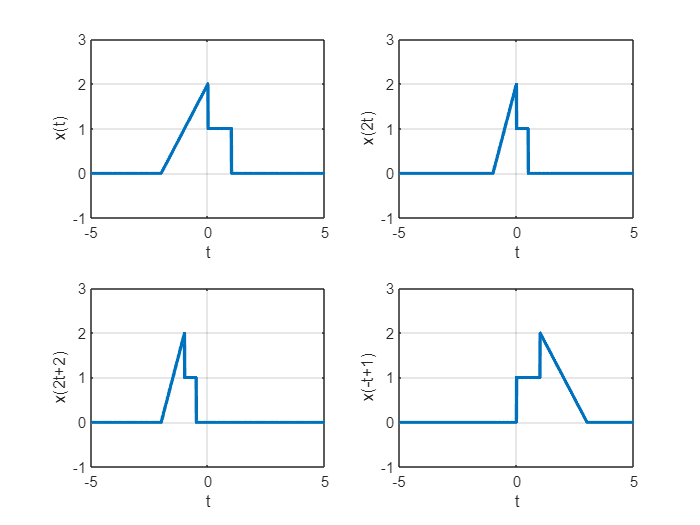

clear; clc; close all

t = linspace(-5, 5, 1000);

u =@(t) 0.5*(sign(t) + 1);
x =@(t) (t+2).*(u(t+2)-u(t)) + (u(t)-u(t-1));


% Plot 1
figure(1);
subplot(2,2,1);
plot(t,x(t), "LineWidth", 2);
ylim([-1,3]);
xlabel('t');
ylabel("x(t)");
grid on;

% Plot 2
figure(1);
subplot(2,2,2);
plot(t,x(2*t), "LineWidth", 2);
ylim([-1,3]);
xlabel('t');
ylabel("x(2t)");
grid on;

% Plot 3
figure(1);
subplot(2,2,3);
plot(t,x(2*t+2), "LineWidth", 2);
ylim([-1,3]);
xlabel('t');
ylabel("x(2t+2)");
grid on;

% Plot 4
figure(1);
subplot(2,2,4);
plot(t,x(-t+1), "LineWidth", 2);
ylim([-1,3]);
xlabel('t');
ylabel("x(-t+1)");
grid on;